clear
clc
close all

syms z w_n s
p = s^2 + 2*z*w_n*s + w_n^2

$$p = s^{2}+2\,z\,s\,w_{n}+{w_{n}}^{2}$$

za = 1;
s_t_a = 2;
wna = 5.8/s_t_a; % sacado de tabla
pa = [1 2*za*wna wna^2];
sys_a = tf(1,pa)

sys_a =
 
          1
  ------------------
  s^2 + 5.8 s + 8.41
 
Continuous-time transfer function.



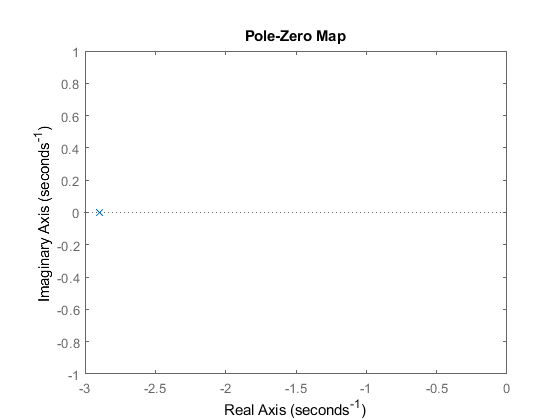

pzmap(sys_a)

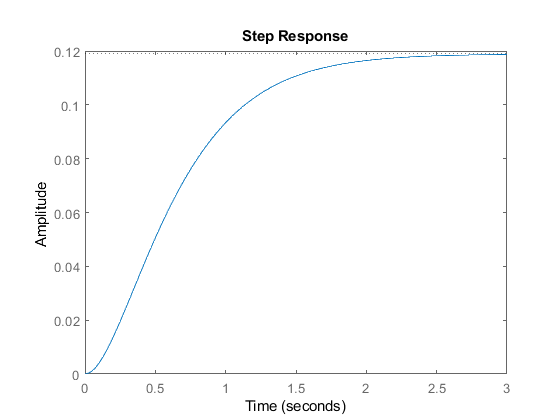

step(sys_a)

stepinfo(sys_a)

ans = struct with fields:
        RiseTime: 1.1579
    SettlingTime: 2.0117
     SettlingMin: 0.1073
     SettlingMax: 0.1188
       Overshoot: 0
      Undershoot: 0
            Peak: 0.1188
        PeakTime: 3.3900


zb = 0.6;
s_t_b = 4;
wnb = 4/(zb*s_t_b);
pb = [1 2*zb*wnb wnb^2];
sys_b = tf(1,pb)

sys_b =
 
          1
  -----------------
  s^2 + 2 s + 2.778
 
Continuous-time transfer function.



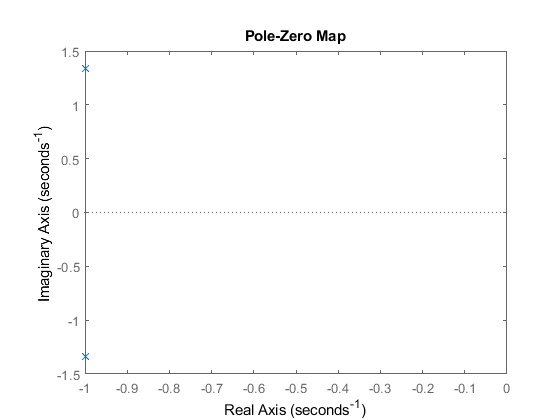

pzmap(sys_b)

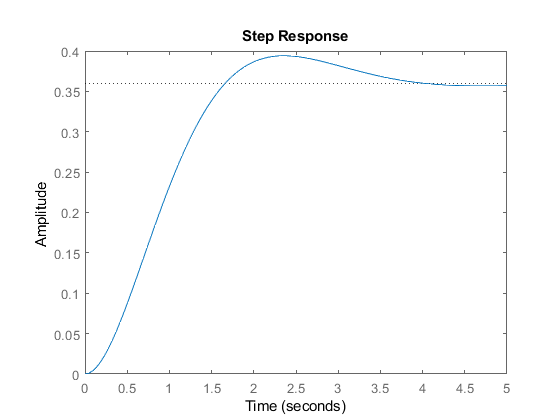

step(sys_b)

stepinfo(sys_b)

ans = struct with fields:
        RiseTime: 1.1134
    SettlingTime: 3.5661
     SettlingMin: 0.3270
     SettlingMax: 0.3941
       Overshoot: 9.4773
      Undershoot: 0
            Peak: 0.3941
        PeakTime: 2.3486
